# Practice 0  Part 1

This version 12/09/2024

This practice is an introduction to the Live Editor. In the Live Editor, you can create live scripts that show output together with the code that produced it. Add formatted text, equations, images, and hyperlinks to enhance your narrative, and share the live script with others as an interactive document.

Create a live script in the Live Editor. To create a live script, on the **Home **tab, click **New Live Script**.

## Add the Inflation Data

Divide your live script into sections. Sections can contain text, code, and output. MATLAB code appears with a gray background and output appears with a white background. To create a new section, go to the **Live Editor **tab and click the **Section Break** button.

Add the Spain Inflation (CPI Index) for 1960 to 2022.

clear all

m1=readtable("CPI_SP.xlsx")

m1 = 63×2 table
    Year    CPISpain
    ____    ________

    1960      1.18  
    1961      0.81  
    1962      5.71  
    1963      8.74  
    1964      6.98  
    1965     13.21  
    1966      6.24  
    1967      6.39  
    1968      4.95  
    1969      2.16  
    1970      5.73  
    1971      8.24  
    1972      8.27  
    1973     11.42  
    1974     15.68  
    1975     16.95  


## Visualize the Inflation Over Time

Sections can be run independently. To run the code in a section, go to the **Live Editor **tab and click the **Run Section** button. You can also click the blue bar that appears when you move the mouse to the left of the section. When you run a section, output and figures appear together with the code that produced them.

Plot the inflation rate date against the year.

CPI_SP=m1.CPISpain

CPI_SP =     1.1800
    0.8100
    5.7100
    8.7400
    6.9800
   13.2100
    6.2400
    6.3900
    4.9500
    2.1600


years_data=m1.Year

years_data =         1960
        1961
        1962
        1963
        1964
        1965
        1966
        1967
        1968
        1969


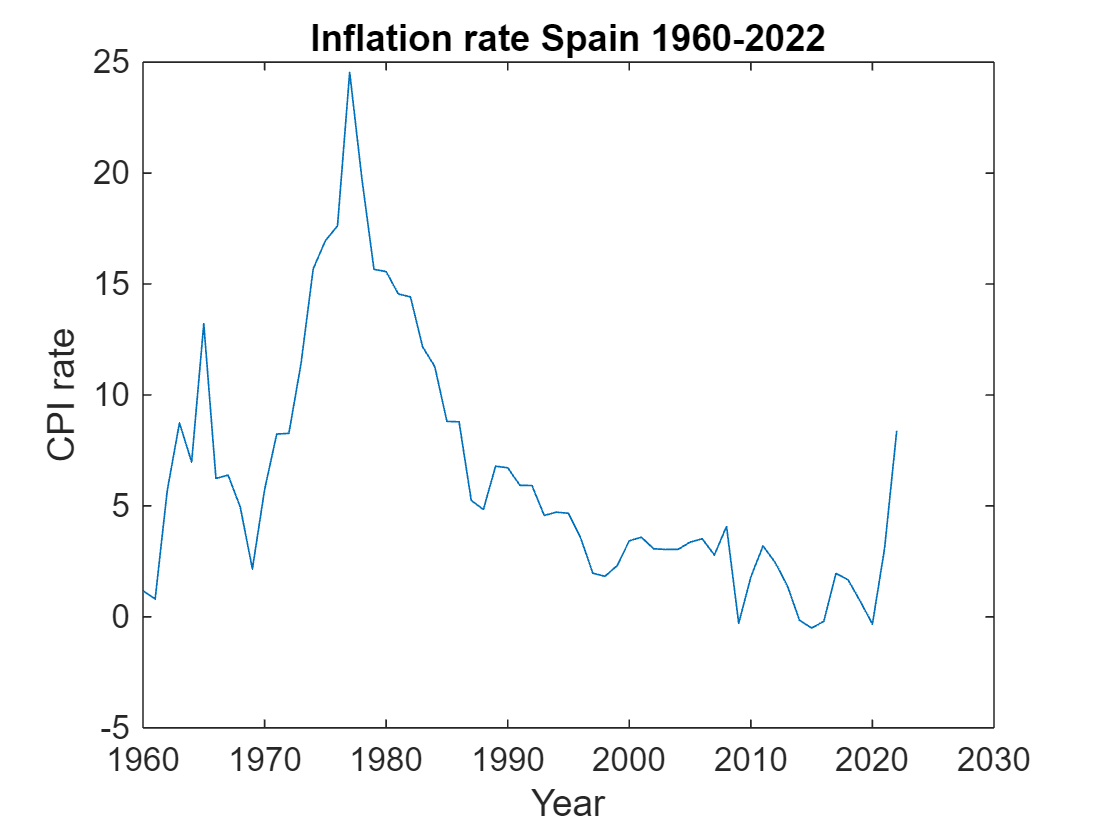

plot(years_data,CPI_SP);                                    % Plot the cpi data

title('Inflation rate Spain 1960-2022');
ylabel('CPI rate');
xlabel('Year')

## Can we predict the Spain inflation rate?

## Fitting the Data

Fit the data with polynomials. Use the MATLAB [`polyfit`](docid:matlab_ref.bue6sxq-1) function to get the coefficients. 

The fit equations are:


$$\begin{array}{ll}y = ax + b & \qquad\mbox{linear}\\ y = ax^2 +bx+c & \qquad\mbox{quadratic}\\ y = ax^3+bx^2+cx+d. & \qquad\mbox{cubic}\\
y=ax^4+bx^3+cx^2+dx+e & \qquad\mbox{fourth-order}\\
\end{array}$$


x = years_data ./ years_data(1,1); % Normalize explanatory variable
coef1 = polyfit(x,CPI_SP,1) 

coef1 =  -317.4566  328.7958


coef2 = polyfit(x,CPI_SP,2)

coef2 = 1.0e+04 *

   -1.9492    3.9282   -1.9783


coef3 = polyfit(x,CPI_SP,3)

coef3 = 1.0e+07 *

    0.4746   -1.4482    1.4730   -0.4994


coef4 = polyfit(x,CPI_SP,4)

coef4 = 1.0e+08 *

   -0.9352    3.8474   -5.9346    4.0679   -1.0455


## Plotting the Curves

Create sections with any number of text and code lines.

We can plot the curves fitted to the data. We'll use the [`polyval`](docid:matlab_ref.f93-999699) function to evaluate the fitted polynomials at the points in `x`.

pred1 = polyval(coef1,x);
pred2 = polyval(coef2,x);
pred3 = polyval(coef3,x);
pred4 = polyval(coef4,x);

% Errors
err1=CPI_SP - pred1;
err2=CPI_SP - pred2;
err3=CPI_SP - pred3;
err4=CPI_SP - pred4;

% R2 = 1 - (SSRES/SSTOT) 
SSTOT= sum((CPI_SP -mean(CPI_SP)).^2);
R2_1= 1 - ((sum(err1.^2))/ SSTOT);
R2_2= 1 - ((sum(err2.^2))/ SSTOT);
R2_3= 1 - ((sum(err3.^2))/ SSTOT);
R2_4= 1 - ((sum(err4.^2))/ SSTOT);

% Table with R2 
Table1=table(R2_1, R2_2,  R2_3, R2_4);
Table1.Properties.VariableNames = {'Linear','Quadratic','Cubic','Fourth-Order'};
vr={'R2'};
Table1.Properties.RowNames = vr

Table1 = 1×4 table
          Linear     Quadratic     Cubic     Fourth-Order
          _______    _________    _______    ____________

    R2    0.28551     0.35957     0.65051      0.65789   



[pred1; pred2; pred3; pred4];

Plot the predicted values for each polynomial.

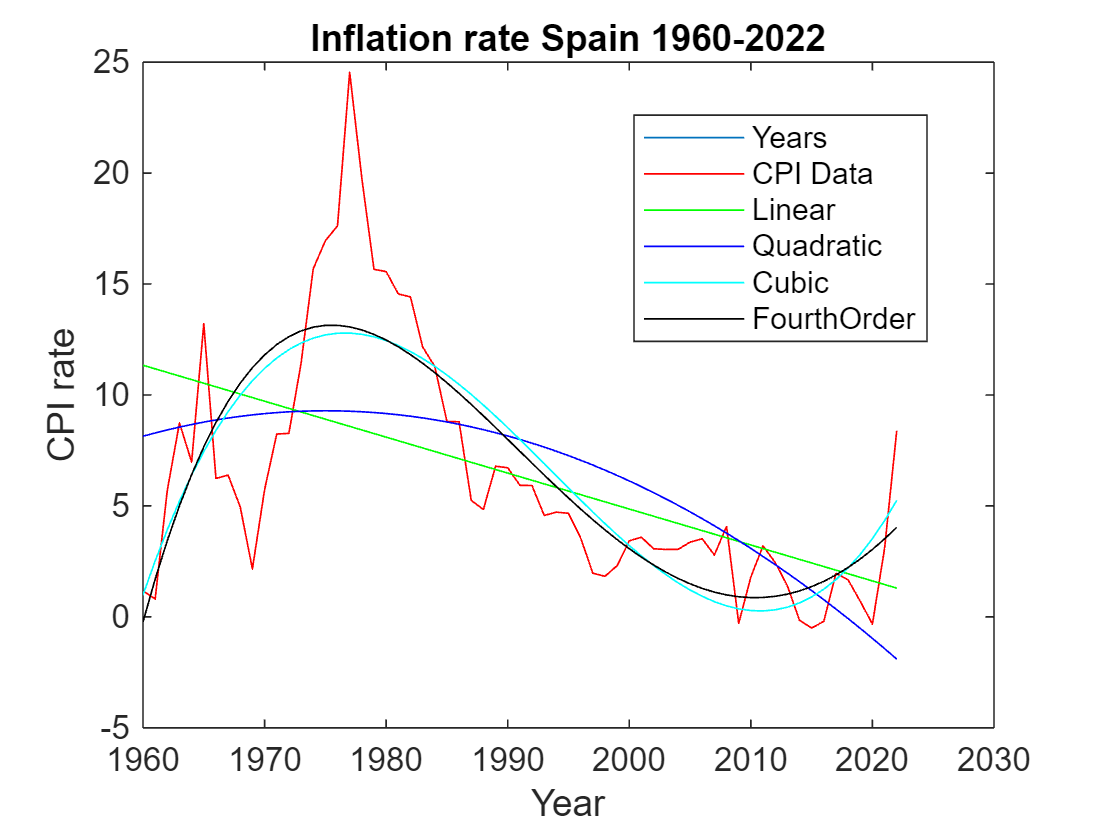

hold on
plot(years_data,CPI_SP,'r');  % red
plot(years_data,pred1,'g')    % green
plot(years_data,pred2,'b')    % blue
plot(years_data,pred3,'c')    % cyan
plot(years_data,pred4,'k')    % black
hold off
legend({'Years' 'CPI Data' 'Linear' 'Quadratic' 'Cubic' 'FourthOrder'},'Location', 'best')

## Predicting the CPI_SP

You can share your live script with other MATLAB users so that they can reproduce your results. You also can publish your results as PDF, Microsoft® Word, or HTML documents. Add controls to your live scripts to show users how important parameters affect the analysis. To add controls, go to the **Live Editor **tab, click the **Control** button, and select from the available options.

We can now calculate the predicted CPI_SP of a given year using our equations.



year = 2024;
xyear = year./ years_data(1,1);
pred1 = polyval(coef1,xyear);
pred2 = polyval(coef2,xyear);
pred3 = polyval(coef3,xyear);
pred4 = polyval(coef4,xyear);
[pred1 pred2 pred3 pred4]

ans =     0.9733   -2.8743    7.4007    5.2151


For the year 2024 for example, the linear predicts low inflation, the quadratic negative inflation, the cubic high inflation and the fourth-order moderate inflation